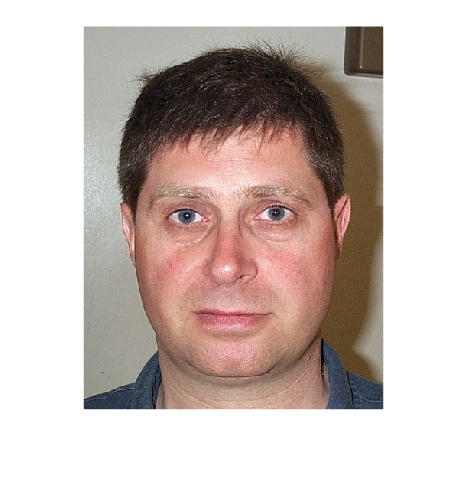

clear 

realId = 1;
im = imread("../Faces/db1_" + realId + ".jpg");
imshow(im)


% Gray world comp start
imR = im(:,:,1);
imG = im(:,:,2);
imB = im(:,:,3);

[m,n,~] = size(im);
R_avg = 1/(m*n)*sum(sum(imR)) 

R_avg = 150.0609

G_avg = 1/(m*n)*sum(sum(imG)) 

G_avg = 122.5832

B_avg = 1/(m*n)*sum(sum(imB))

B_avg = 111.8482

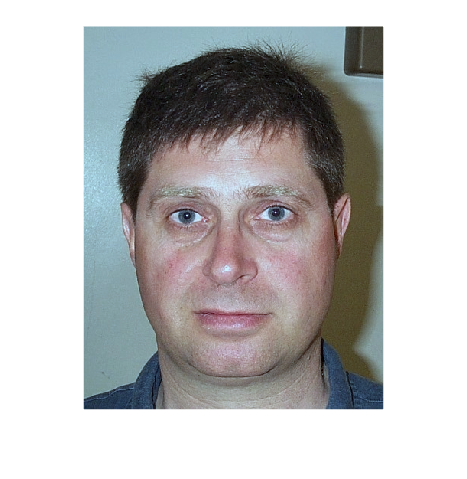


minAvgDiff = 6;

% Kan bli problematiskt med mycket färger i bakgrunden
if abs(R_avg - G_avg) > minAvgDiff || abs(R_avg - B_avg) > minAvgDiff || abs(B_avg - G_avg) > minAvgDiff
    alpha = G_avg / R_avg;
    beta = G_avg / B_avg;

    im(:,:,1) = alpha * imR;
    im(:,:,3) = beta  * imB;
end    
imshow(im)

% Gray world comp end

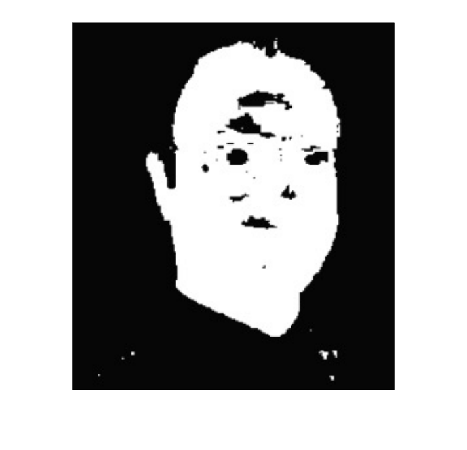

% Fylla hål för mask start
im = imread("badMask.png");
im = im(:,:,1);
imshow(im)

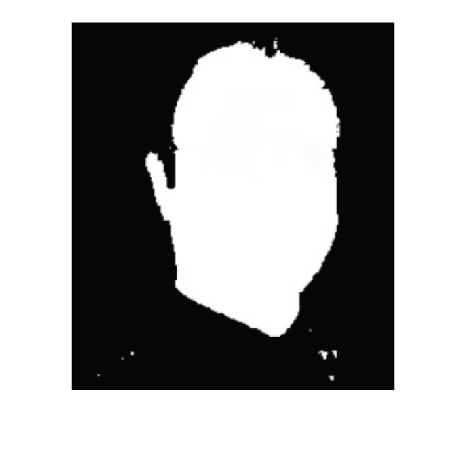

im = imfill(im, 'holes');
imshow(im)

% Fylla hål för mask end

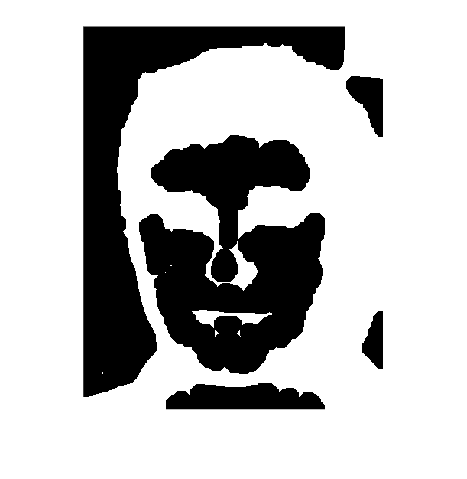

% Color-based method start
realId = 1;
im = imread("../Faces/db1_" + realId + ".jpg");

im = sum(im,3)./(3*255);
im = ( im - min(min(im)) )/( max(max(im)) - min(min(im)) );
im = im > 0.5;

r = 12;
SE = strel('disk',r);
im2 = ~imopen(im, SE);% behåller bara det som INTE passar i SE
imshow(im2)

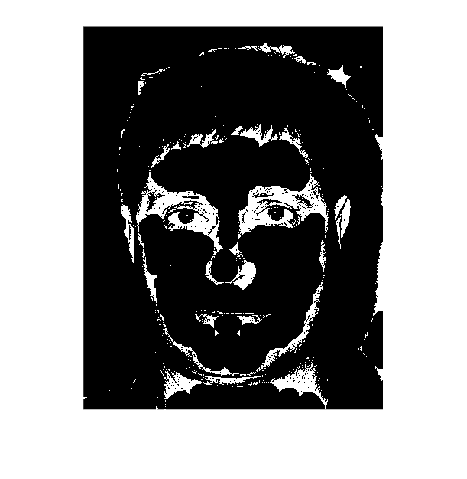

im = im .* im2;
imshow(im)

% Color-based method end


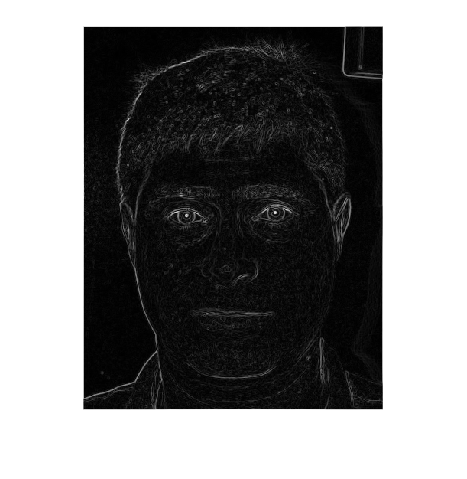

realId = 1;
im = imread("../Faces/db1_" + realId + ".jpg");
imGray = rgb2gray(im);

% Define the Sobel kernels for horizontal and vertical edge detection
sobelY = [-1, 0, 1; -2, 0, 2; -1, 0, 1];% Horizontal
sobelX = [-1, -2, -1; 0, 0, 0; 1, 2, 1];% Vertical

% Perform convolution with Sobel kernels to detect edges
edgesY = conv2(double(imGray), sobelY, 'same');
edgesX = conv2(double(imGray), sobelX, 'same');

% Calculate the magnitude of the edges
imSobel = sqrt(edgesY.^2 + edgesX.^2);

% Adjust the edge magnitude to the range [0, 255]
imSobel = uint8(255 * (imSobel / max(imSobel(:))));

imshow(imSobel)


r = 12;
SE = strel('disk',r);
im2 = ~imopen(im, SE);% behåller bara det som INTE passar i SE